## Loading files

clc
clear

files = dir('./newTrain/*.csv');
for i=1:length(files)
    load(strcat(files(i).folder,'\',files(i).name));
end

Validation load and scale

files = dir('./newValid/*.csv');
for i=1:length(files)
    load(strcat(files(i).folder,'\',files(i).name));
end

## Sample data

load("trainingDataLoaded.mat")
load("validationDataLoaded.mat")
OP_offset = 90; %80
setpoints = 17;
offset = OP_offset * setpoints;
offset_F9 = floor(offset / 14);
offset_F9_mod = mod(offset,14);
% OP_offset = 50;
trainingData = zeros(21*offset,14);
for j=1:setpoints
    n = (j-1)*OP_offset;
    startPoint = 6000*j+5000;
    endPoint = startPoint + OP_offset - 1;
    trainingData(offset*0+n+1:offset*0+j*OP_offset,:) = Ftrain1(startPoint:endPoint,:);
    trainingData(offset*1+n+1:offset*1+j*OP_offset,:) = Ftrain2(startPoint:endPoint,:);
    trainingData(offset*2+n+1:offset*2+j*OP_offset,:) = Ftrain3(startPoint:endPoint,:);
    trainingData(offset*3+n+1:offset*3+j*OP_offset,:) = Ftrain4(startPoint:endPoint,:);
    trainingData(offset*4+n+1:offset*4+j*OP_offset,:) = Ftrain5(startPoint:endPoint,:);
    trainingData(offset*5+n+1:offset*5+j*OP_offset,:) = Ftrain6(startPoint:endPoint,:);
    trainingData(offset*6+n+1:offset*6+j*OP_offset,:) = Ftrain7(startPoint:endPoint,:);
    trainingData(offset*7+n+1:offset*7+j*OP_offset,:) = Ftrain8(startPoint:endPoint,:);
    if j < 14
        trainingData(offset*8+(j-1)*offset_F9+1 : offset*8+j*offset_F9,:) = Ftrain9(startPoint : startPoint + offset_F9-1,:);
    elseif j == 14 
        trainingData(offset_F9*8+(j-1)*offset_F9+1 : offset_F9*8+j*offset_F9+offset_F9_mod,:) = Ftrain9(startPoint : startPoint + offset_F9 + offset_F9_mod-1,:);
    end
    trainingData(offset*9+n+1:offset*9+j*OP_offset,:) = Ftrain10(startPoint:endPoint,:);
    trainingData(offset*10+n+1:offset*10+j*OP_offset,:) = Ftrain11(startPoint:endPoint,:);
    trainingData(offset*11+n+1:offset*11+j*OP_offset,:) = Ftrain12(startPoint:endPoint,:);
    trainingData(offset*12+n+1:offset*12+j*OP_offset,:) = Ftrain13(startPoint:endPoint,:);
    trainingData(offset*13+n+1:offset*13+j*OP_offset,:) = Ftrain14(startPoint:endPoint,:);
    trainingData(offset*14+n+1:offset*14+j*OP_offset,:) = Ftrain15(startPoint:endPoint,:);
    trainingData(offset*15+n+1:offset*15+j*OP_offset,:) = Ftrain16(startPoint:endPoint,:);
    trainingData(offset*16+n+1:offset*16+j*OP_offset,:) = Ftrain17(startPoint:endPoint,:);
    trainingData(offset*17+n+1:offset*17+j*OP_offset,:) = Ftrain18(startPoint:endPoint,:);
    trainingData(offset*18+n+1:offset*18+j*OP_offset,:) = Ftrain19(startPoint:endPoint,:);
    trainingData(offset*19+n+1:offset*19+j*OP_offset,:) = Ftrain20(startPoint:endPoint,:);
    trainingData(offset*20+n+1:offset*20+j*OP_offset,:) = Ntrain1_2(startPoint:endPoint,:);
end


ValidationData = [NewValid_f1(9001:end,:); NewValid_f2(9001:end,:); NewValid_f3(9001:end,:); NewValid_f4(9001:end,:); NewValid_f5(9001:end,:); NewValid_f6(9001:end,:); NewValid_f7(9001:end,:); NewValid_f8(9001:end,:); NewValid_f9(9001:end,:); NewValid_f10(9001:end,:); NewValid_f11(9001:end,:); NewValid_f12(9001:end,:); NewValid_f13(9001:end,:); NewValid_f14(9001:end,:); NewValid_f15(9001:end,:); NewValid_f16(9001:end,:); NewValid_f17(9001:end,:); NewValid_f18(9001:end,:); NewValid_f19(9001:end,:); NewValid_f20(9001:end,:); NewValid_n1_2(5001:end,:)];

Label

N = offset;
trainingLabel = zeros(1,N*21);
Nk = zeros(1,21);
for i=1:21
    trainingLabel(1,(i-1)*N+1:i*N) = i*ones(1,N);
    Nk(i) = N;
end

N=1000;
for i=1:20
    validationLabel(1,(i-1)*N+1:i*N) = i*ones(1,N);
end
validationLabel(1,20*1000+1:20*1000+1000) = 21*ones(1,1000);

Noise

% Noise to Tdis, Tret, Tsuc, Tsup
% trainingData(:,5) = trainingData(:,5) + normrnd(0,sqrt(2),25200,1);
% trainingData(:,6) = trainingData(:,6) + normrnd(0,sqrt(2),25200,1);
% trainingData(:,7) = trainingData(:,7) + normrnd(0,sqrt(2),25200,1);
% trainingData(:,9) = trainingData(:,9) + normrnd(0,sqrt(2),25200,1);

% Noise to Tdis, Tret, Tsuc, Tsup
% ValidationData(:,5) = ValidationData(:,5) + normrnd(0,sqrt(2),103000,1);
% ValidationData(:,6) = ValidationData(:,6) + normrnd(0,sqrt(2),103000,1);
% ValidationData(:,7) = ValidationData(:,7) + normrnd(0,sqrt(2),103000,1);
% ValidationData(:,9) = ValidationData(:,9) + normrnd(0,sqrt(2),103000,1);

Remove data

% Psuc, CprPower, Density
% trainingData(:,12) = [];
% trainingData(:,11) = [];
% trainingData(:,2) = [];
% 
% ValidationData(:,12) = [];
% ValidationData(:,11) = [];
% ValidationData(:,2) = [];
% trainingData_20 = trainingData;
% trainingLabel_20 = trainingLabel;
% save('trainingData_OG.mat',"trainingData","trainingLabel")
% save('ValidationData_OG_smaller.mat',"ValidationData","validationLabel")

Reduce data

W_PCA = PCA_Train(trainingData, 2);

Unable to perform assignment because the size of the left side is 11-by-1 and the size of the right side is 14-by-1.

Error in generateData>PCA_Train (line 152)
        W(:,i) = V(I(i),:)';

trainingData_PCA = (W_PCA.' * trainingData.').';
validationData_PCA = (W_PCA.' * ValidationData.').';

W_LDA = LDA_Train(trainingData, trainingLabel, 4, 1200);
trainingData_LDA = (W_LDA.' * trainingData.').';
validationData_LDA = (W_LDA.' * ValidationData.').';

## Preprocessing

% Normalize Data

% Normalize Data
[normalizedData,centerValue,scaleValue] = normalize(trainingData,"center",...
    "scale");
normalizedData
trainingData = normalizedData
ValidationData = (ValidationData - centerValue) ./ scaleValue;
plot(ValidationData)


LDA

% Normalize Data
[normalizedData_LDA,centerValue_LDA,scaleValue_LDA] = normalize(trainingData_LDA,"center",...
    "scale");
trainingData_LDA = normalizedData_LDA;
validationData_LDA = (validationData_LDA - centerValue_LDA) ./ scaleValue_LDA;
plot(validationData_LDA)

PCA

% Normalize Data
[normalizedData_PCA,centerValue_PCA,scaleValue_PCA] = normalize(trainingData_PCA,"center",...
    "scale");
trainingData_PCA = normalizedData_PCA;
validationData_PCA = (validationData_PCA - centerValue_PCA) ./ scaleValue_PCA;
plot(validationData_PCA)

% Do-not uncomment these
% save('trainingData_nn.mat',"trainingData", "trainingData_LDA", "trainingData_PCA" ,"trainingLabel")
% save('ValidationData_nn.mat',"ValidationData", "validationData_LDA", "validationData_PCA" ,"validationLabel")

## plotting

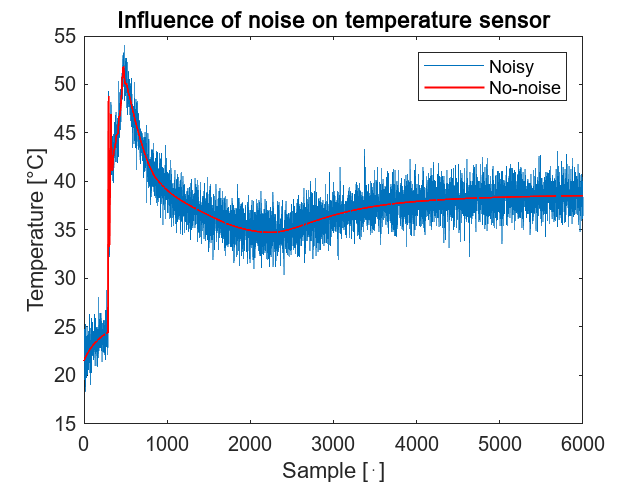


figure()
x = linspace(1,6000,6000);
plot(x,Ntrain1_2(30001:36000,5) + normrnd(0,sqrt(2),6000,1))
hold on
plot(x,Ntrain1_2(30001:36000,5),Color=[1,0,0],LineWidth=1)
hold off
title("Influence of noise on temperature sensor")
ylabel("Temperature [°C]")
xlabel("Sample [⋅]")
legend("Noisy","No-noise")
saveas(gcf,'Images/NoisyData','epsc')


Ftrain5(:,11) = Ftrain5(:,11) ./ 1000

Ftrain5 =     7.9542    2.6651   -2.5694   31.1261   46.6062    5.1626    3.1444    5.7138    0.0035   45.8456    1.1242    5.9834         0   10.0000
    6.9542    2.6651   -2.5694   31.1261   46.6062    5.1626    3.1444    5.7138    0.0035   45.8457    1.1242    5.9834         0   10.0000
    6.9542    2.6651   -2.5694   26.4905   46.6063    5.1627    3.1444    5.7138    0.0035         0    1.1242    5.9834         0   10.0000
    6.9568    2.6651   -2.5694   26.4905   46.6225    5.1627    3.1444    5.7138    0.0035         0    1.1241    5.9834         0   10.0000
    6.9752    2.6652   -2.5694   26.5032   46.7278    5.1627    3.1443    5.7137    0.0033         0    1.1234    5.9837         0   10.0000
    7.0223    2.6656   -2.5681   26.5924   46.9886    5.1627    3.1438    5.7125    0.0017         0    1.1245    5.9846         0   10.0000
    7.0879    2.6665   -2.5640   26.8213   47.3355    5.1627    3.1416    5.7078   -0.0031         0    1.1294    5.9867         0   10.0000
   


figure()
x = linspace(6001,12000,6000);
fig = figure;
subplot(2,1,1)
plot(Ntrain1_2(1:6000,:),LineWidth=1)
title("Non-faulty")
ylim([-10 90])
subplot(2,1,2)
plot(x,Ftrain5(6001:12000,:),LineWidth=1)'

ans =   1×14 Line array:

    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line


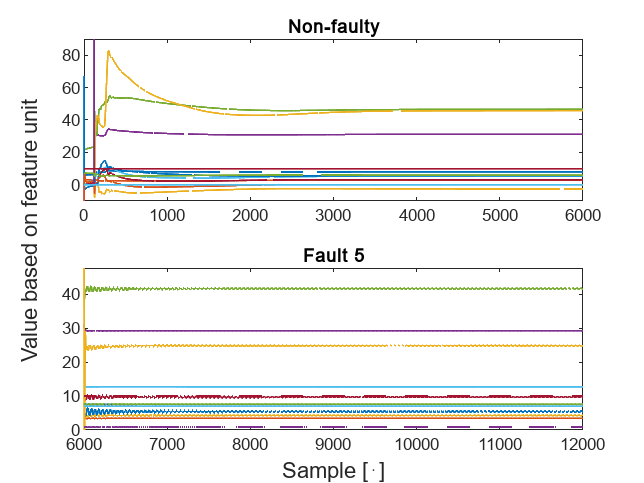

title("Fault 5")
handle = axes(fig,'visible','off');
handle.XLabel.Visible='on';
handle.YLabel.Visible='on';
xlabel(handle,"Sample [⋅]")
ylabel(handle,"Value based on feature unit")
saveas(gcf,'Images/dataSample','epsc')

## Functions

### PCA:

function W = PCA_Train(data, D)
    sigma = cov(data);
    [V, e] = eig(sigma);
    [e_sort, I] = sort(diag(e),'descend');

    W = zeros(11, D);
    for i=1:D
        W(:,i) = V(I(i),:)';
    end
end

### LDA:

function W = LDA_Train(data, label, D, Nk)
    % Calculate mean of each class
    for i=1:21
        mu(i,:)= mean(data(label == i,:));
    end
    % Calculate total mean
    mu(22,:) = mean(data);

    % Calculate within-class scattesr
    Sw = 0;
    for j=1:size(mu,1)-1
        Sw = Sw + (data(find(label==j),:)' - mu(j,:)') * (data(find(label==j),:)' - mu(j,:)')';
    end
    % Calculate between-class scatter
    Sb = Nk .* (mu(1:21,:)' - mu(22,:)') * (mu(1:21,:)' - mu(22,:)')';

    % Use the eigenvalue decomposition and sort it in decending order
    [V e] = eig(Sb,Sw);
    [B,I] = sort(diag(e),'descend');

    % Take D number of eigenvectores corresponding to the largest values
    for i=1:D
        W(:,i) = V(:,I(i));
    end
end